# 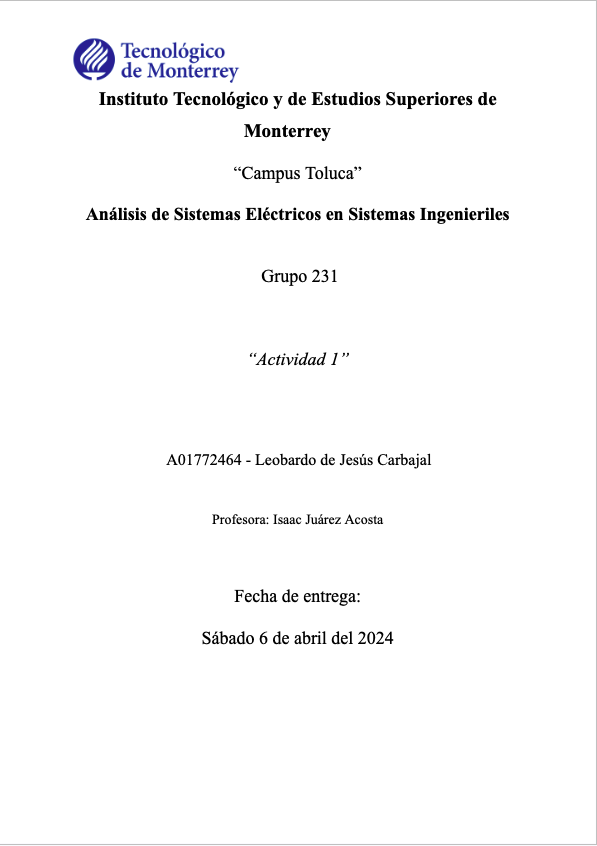

Definir la función

f = @(x) x + (2 ./ x.^2);


Definir límites de intervalos

a = -5;
b = 5;

% Valor inicial de xi
xi = 4; 

% Error inicial
e = 1; 

% Número de iteración inicial
n = 0;


Format long

format long;


Bucle while

disp('---------------------------------------');

---------------------------------------


disp('|   n   |      xnew      |       e      |');

|   n   |      xnew      |       e      |


disp('---------------------------------------');

---------------------------------------


while abs(e) > 0.000001
    % Calcular el nuevo valor de x
    xnew = (a + b) / 2;
    
    % Actualizar los límites del intervalo
    if f(xnew) > 0
        b = xnew;
    elseif f(xnew) < 0
        a = xnew;
    end
    
    % Calcular el error
    e = (xnew - xi) / xnew;
    
    % Actualizar el valor previo de xi
    xi = xnew;
    
    % Incrementar el número de iteraciones
    n = n + 1;
    
    % Imprimir los resultados en una tabla
    disp(['|   ', num2str(n), '   |   ', num2str(xnew), '   |  ', num2str(e), '  |']);
end

|   1   |   0   |  -Inf  |
|   2   |   -2.5   |  1  |
|   3   |   -1.25   |  -1  |
|   4   |   -1.875   |  0.33333  |
|   5   |   -1.5625   |  -0.2  |
|   6   |   -1.4062   |  -0.11111  |
|   7   |   -1.3281   |  -0.058824  |
|   8   |   -1.2891   |  -0.030303  |
|   9   |   -1.2695   |  -0.015385  |
|   10   |   -1.2598   |  -0.0077519  |
|   11   |   -1.2646   |  0.003861  |
|   12   |   -1.2622   |  -0.0019342  |
|   13   |   -1.261   |  -0.00096805  |
|   14   |   -1.2604   |  -0.00048426  |
|   15   |   -1.2601   |  -0.00024219  |
|   16   |   -1.2599   |  -0.00012111  |
|   17   |   -1.26   |  6.0551e-05  |
|   18   |   -1.26   |  -3.0276e-05  |
|   19   |   -1.2599   |  -1.5138e-05  |
|   20   |   -1.2599   |  -7.5693e-06  |
|   21   |   -1.2599   |  -3.7847e-06  |
|   22   |   -1.2599   |  -1.8923e-06  |
|   23   |   -1.2599   |  9.4616e-07  |


disp('---------------------------------------');

---------------------------------------
